# Task 6: Robot Calibration Given Real Data

#### Write your own code to find the position and orientation of the World frame  with respect to the robot frame, given the positions of the checkerboard corner points.

World Coordinate System: (TCP position wrt normal base of robot) EXPERIMENTALLY MEASURED

Xi = [84 84 84 42 126 126 21];
Yi = [84 105 0 42 21 84 84];
Zi = [0 0 0 0 0 0 0];

Xri = zeros(1,length(Xi))

Xri =      0     0     0     0     0     0     0


Yri = zeros(1,length(Yi))

Yri =      0     0     0     0     0     0     0


Zri = zeros(1,length(Zi))

Zri =      0     0     0     0     0     0     0


Associated joint Angle Values from Arduino serial monitor:

theta1 = [102.37 98.98 80.36 78.76 83.41 100.31 103.56]

theta1 =   102.3700   98.9800   80.3600   78.7600   83.4100  100.3100  103.5600


theta2 = [54.75 55.55 55.42 74.81 39.26 38.33 77.96]

theta2 =    54.7500   55.5500   55.4200   74.8100   39.2600   38.3300   77.9600


theta3 = [101.77 102.95 102.75 131.28 79.94 78.48 139.02]

theta3 =   101.7700  102.9500  102.7500  131.2800   79.9400   78.4800  139.0200


### Link Lengths:

L1 = 0.093;     % measured to approx degree by visual inspection (metres)
L2 = 0.170 + 0.03; % Frame 3 to gripper centre, plus gripper centre to toothpick tip

#### Robot Parameters:

a0 = 0;
a1 = 0;
a2 = L1;

alpha0 = 0;
alpha1 = -90;
alpha2 = 180;

alpha0 = alpha0 * pi/180;
alpha1 = alpha1 * pi/180;
alpha2 = alpha2 * pi/180;

d1 = 0;
d2 = 0;
d3 = 0;

for i = 1:1:length(theta1)

    % converting to radians
    theta1(i) = theta1(i)*pi/180;
    theta2(i) = theta2(i)*pi/180;
    theta3(i) = theta3(i)*pi/180;
    % Creating 0-3Transforamtion Matrix from 0-1T then 1-2T then 2-3T
    T01 = [cos(theta1(i)) -sin(theta1(i)) 0 a0;
        cos(alpha0).*sin(theta1(i)) cos(alpha0).*cos(theta1(i)) -sin(alpha0)  -sin(alpha0)*d1;
        sin(alpha0).*sin(theta1(i))  sin(alpha0).*cos(theta1(i))  cos(alpha0)  cos(alpha0)*d1;
        0 0 0 1];
    T12 = [cos(theta2(i)) -sin(theta2(i)) 0 a1;
        cos(alpha1).*sin(theta2(i)) cos(alpha1).*cos(theta2(i)) -sin(alpha1)  -sin(alpha1)*d2;
        sin(alpha1).*sin(theta2(i))  sin(alpha1).*cos(theta2(i))  cos(alpha1)  cos(alpha1)*d2;
        0 0 0 1];
    T23 = [cos(theta3(i)) -sin(theta3(i)) 0 a2;
        cos(alpha2).*sin(theta3(i)) cos(alpha2).*cos(theta3(i)) -sin(alpha2)  -sin(alpha2)*d3;
        sin(alpha2).*sin(theta3(i))  sin(alpha2).*cos(theta3(i))  cos(alpha2)  cos(alpha2)*d3;
        0 0 0 1];
    % Now individual transform matricies have been calculated, we can find T03
    % using a compound transform:
    T03 = T01*T12*T23;
    % Position of End Effector FROM FRAME 3
    P3 = [L2;0;0;1];
    % Position of End Effector FROM FRAME 0 --> FINAL ANSWER
    P0 = T03*P3;
    % Add robot frame Cartesian position to robot frame coordinate matrices
    Xri(i) = P0(1);
    Yri(i) = P0(2);
    Zri(i) = P0(3);
end

Positions according to Robot Coordinate System in m:

Xri

Xri =    -0.0407   -0.0293    0.0315    0.0263    0.0257   -0.0404   -0.0272


Yri

Yri =     0.1856    0.1857    0.1857    0.1323    0.2222    0.2222    0.1129


Zri

Zri =     0.0704    0.0705    0.0705    0.0770    0.0715    0.0713    0.0841


Positions according to Robot Coordinate System in mm:

Xri = Xri*1000

Xri =   -40.7075  -29.3424   31.5385   26.2834   25.6704  -40.4169  -27.2395


Yri = Yri*1000

Yri =   185.6116  185.6799  185.6783  132.2563  222.2027  222.1796  112.9395


Zri = Zri*1000

Zri =    70.3707   70.5297   70.4838   76.9686   71.5126   71.2805   84.0712


We know relationship between pRCS and pWCS  (p82)

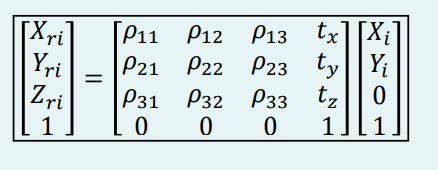

Use Cashbaugh Method to find all rhos and ts:

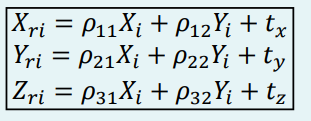

## Can then calculate rotation and translation parameters for 1st set:

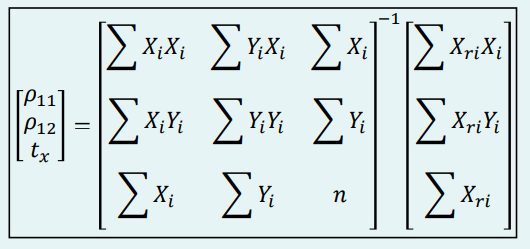

We then need to calculate the following sums:

% Setting sums to zero initially
sumXiXi = 0;
sumYiYi = 0;
sumYiXi = 0;
sumXiYi = 0;
sumXi = 0;
sumYi = 0;
sumXriXi = 0;
sumXriYi = 0;
sumXri = 0;
sumYriXi = 0;
sumYriYi = 0;
sumYri = 0;

sumZriXi = 0;
sumZriYi = 0;
sumZri = 0;

n = length(Xi);

% length(Xi) = length(Yi) is 6 in this case - (number of points)

for i=1:n
    sumXiXi = sumXiXi + Xi(i)*Xi(i);
    sumYiYi = sumYiYi + Yi(i)*Yi(i);
    sumYiXi = sumYiXi + Yi(i)*Xi(i);
    sumXiYi = sumXiYi + Xi(i)*Yi(i);
    sumXi = sumXi + Xi(i);
    sumYi = sumYi + Yi(i);
    
    sumXriXi = sumXriXi + Xri(i)*Xi(i);
    sumXriYi = sumXriYi + Xri(i)*Yi(i);
    sumXri = sumXri + Xri(i);
    
    sumYriXi = sumYriXi + Yri(i)*Xi(i);
    sumYriYi = sumYriYi + Yri(i)*Yi(i);
    sumYri = sumYri + Yri(i);
    
    sumZriXi = sumZriXi + Zri(i)*Xi(i);
    sumZriYi = sumZriYi + Zri(i)*Yi(i);
    sumZri = sumZri + Zri(i);
    
end

#### Now that all the sums have been found, we can place them in the matrix, invert it and multiply it by the RHS matrix:

k is the LHS matrix

a = [sumXiXi sumYiXi sumXi; sumXiYi sumYiYi sumYi; sumXi sumYi n];
k = inv(a);

m = [sumXriXi sumXriYi sumXri]';

LHSmatrix = k*m;

Now taking each element of the solution and storing them in variables given:

rho11 = LHSmatrix(1)

rho11 = -0.1411

rho12 = LHSmatrix(2)

rho12 = -0.8136

tx = LHSmatrix(3)

tx = 52.4946

## Can then calculate rotation and translation parameters for 2nd set:

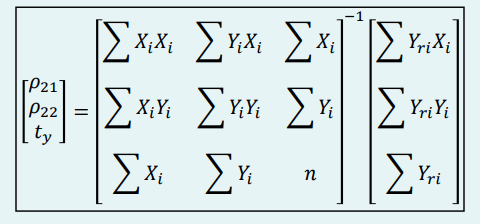

Sums have already been calculated.

#### Now that all the sums have been found, we can place them in the matrix, invert it and multiply it by the RHS matrix:

k is the LHS matrix

a = [sumXiXi sumYiXi sumXi; sumXiYi sumYiYi sumYi; sumXi sumYi n];
k = inv(a);

m = [sumYriXi sumYriYi sumYri]';

LHSmatrix = k*m;

Now taking each element of the solution and storing them in variables given:

rho21 = LHSmatrix(1)

rho21 = 1.0605

rho22 = LHSmatrix(2)

rho22 = 0.0148

ty = LHSmatrix(3)

ty = 91.2948

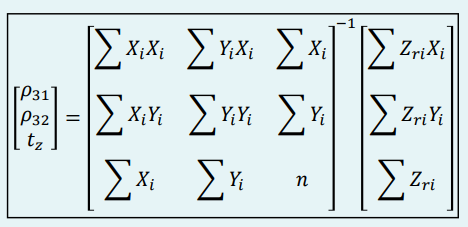

## Finally repreating the process for the 3rd terms:

#### Now that all the sums have been found, we can place them in the matrix, invert it and multiply it by the RHS matrix:

k is the LHS matrix

a = [sumXiXi sumYiXi sumXi; sumXiYi sumYiYi sumYi; sumXi sumYi n];
k = inv(a);

m = [sumZriXi sumZriYi sumZri]';

LHSmatrix = k*m;

Now taking each element of the solution and storing them in variables given:

rho31 = LHSmatrix(1)

rho31 = -0.1066

rho32 = LHSmatrix(2)

rho32 = 0.0044

tz = LHSmatrix(3)

tz = 81.9730

## For final calculations:

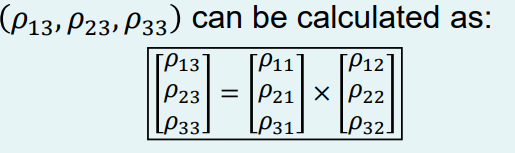

LHSmatrix = cross([rho11 rho21 rho31]', [rho12 rho22 rho32]');

rho13 = LHSmatrix(1)

rho13 = 0.0062

rho23 = LHSmatrix(2)

rho23 = 0.0873

rho33 = LHSmatrix(3)

rho33 = 0.8607


Trw_Lab = [rho11 rho12 rho13 tx; rho21 rho22 rho23 ty; rho31 rho32 rho33 tz; 0 0 0 1]

Trw_Lab =    -0.1411   -0.8136    0.0062   52.4946
    1.0605    0.0148    0.0873   91.2948
   -0.1066    0.0044    0.8607   81.9730
         0         0         0    1.0000


save('Trw_Lab.mat', 'Trw_Lab')